If not found go run `Normalize.ipynb`

% load data/cleaned-hourly.mat -mat data
load data/normalized-hourly.mat -mat data

Specify another colormap by passing the *handle *to it's function as the third param, eg `@spring`

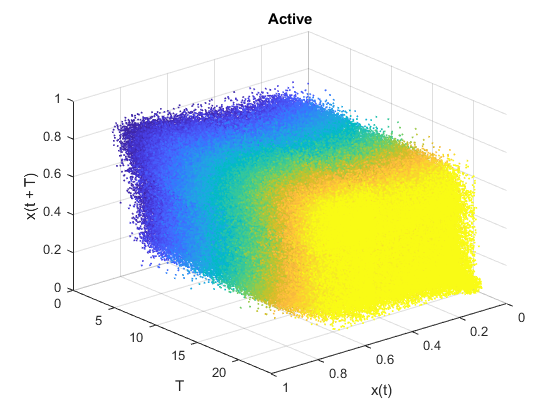

laglag(data.active, 24);
title('Active');

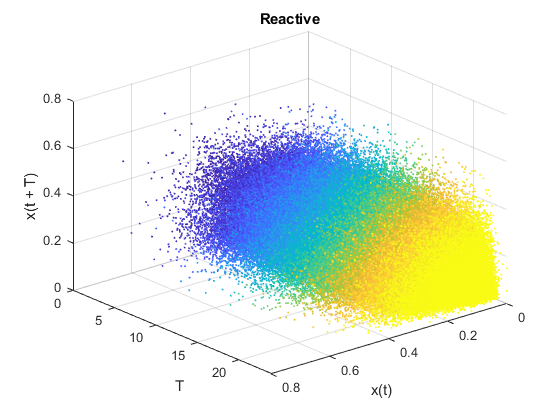

laglag(data.reactive, 24);
title('Reactive');

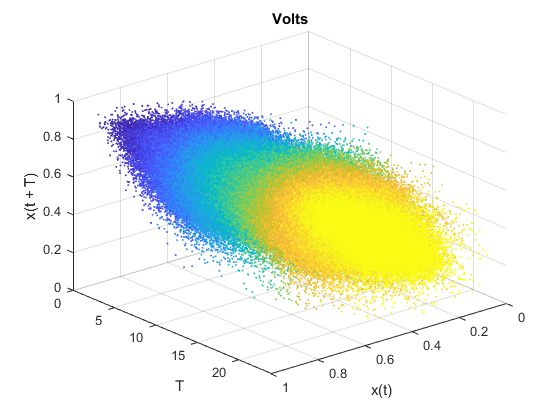

laglag(data.volts, 24);
title('Volts');

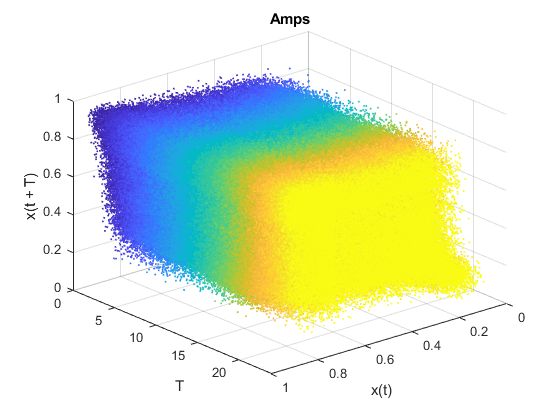

laglag(data.amps, 24);
title('Amps');

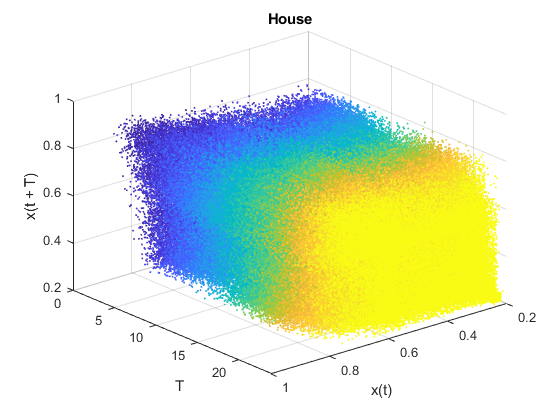

laglag(data.house, 24);
title('House');

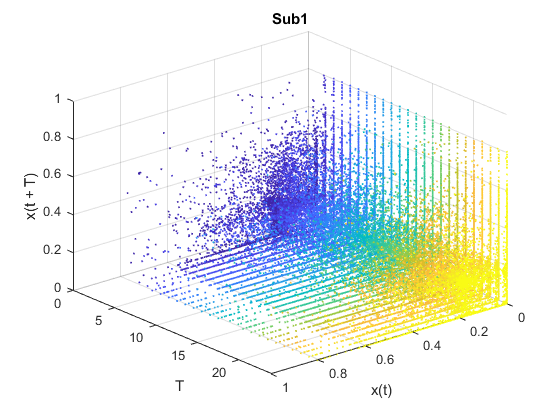

laglag(data.sub1, 24);
title('Sub1');

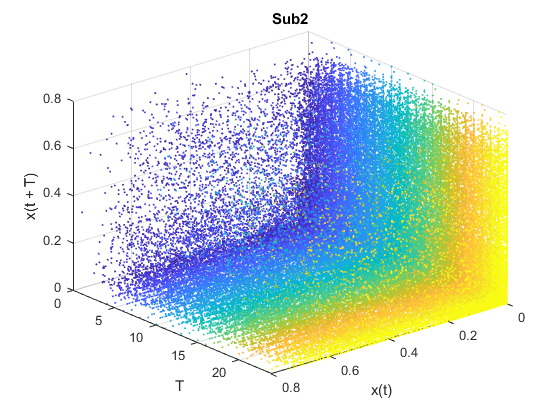

laglag(data.sub2, 24);
title('Sub2');

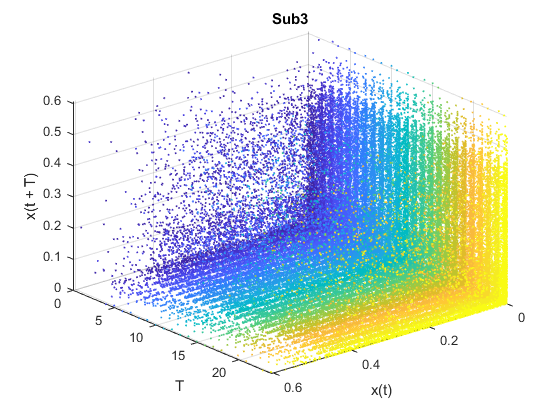

laglag(data.sub3, 24);
title('Sub3');

function laglag(x, lags, cmap)
    if nargin == 2
        cmap = @parula;
    end
    
    colors = cmap(lags);
    figure;
    grid on; hold on;
    view([-220 30])
    xlabel('x(t)'); ylabel('T'); zlabel('x(t + T)');
    
    len = length(x);
    for lag = 1:lags
        shift = [repelem(NaN, lag), x(1:(end-lag))];
        scatter3(x, repelem(lag, len), shift, 1, colors(lag, :))
    end
end